Parameters

fc = 2000; %2kHz
fs = 44.1e3;

Text Encoding

text = ['hello world, vicky was in the musical. ' ...
    'Yichen does not wear glasses' ...
    'Yichen smushed matlab' ...
    'turns out implementation is hard' ...
    'Vicky is happy she is a software engineering'...
    'Yichen is suprised by Vickys career choise'];
text_bin = dec2bin(double(text));
s = size(text_bin);
bin_str = reshape(text_bin.'-'0',1,[]);
% a = [];
% for c=1:length(bin_str)
%     append(a, str2double(bin_str(c)));
% end

Pulse Shaping

%pulse = (sqrt(2)*cos(2*pi*fc*time)).* bin_str;

Transmit

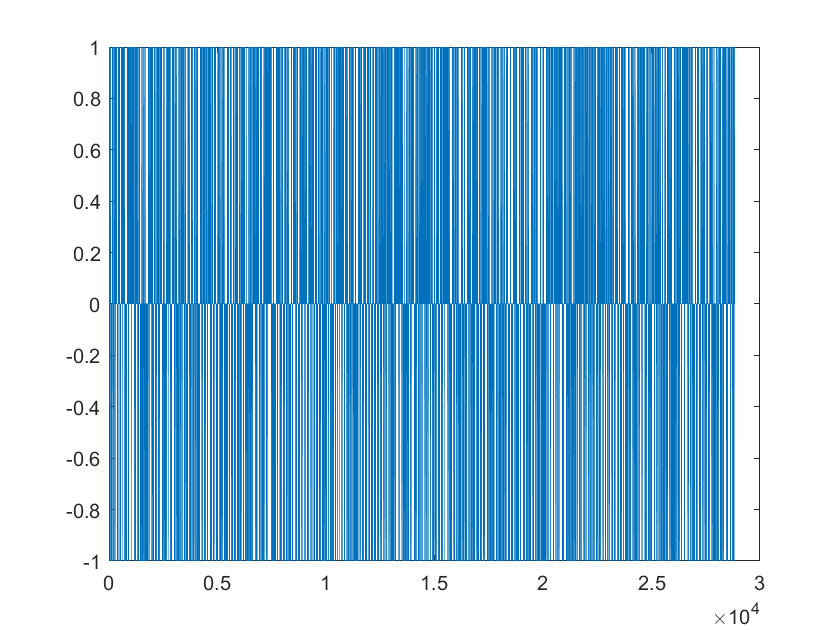

bin_str = 2 * bin_str - 1;
bin_str_us = upsample(bin_str, 20);
plot(bin_str_us);

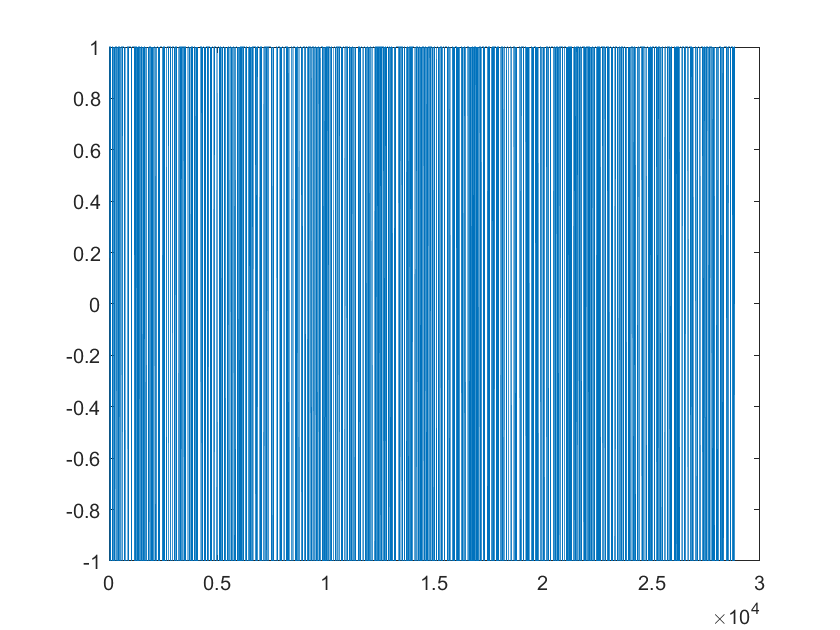

pulse = ones(20, 1);
X_I = conv(bin_str_us, pulse);
plot(X_I);

time = linspace(0,1/fs,length(X_I));  %update to the length of the binary string
X = X_I .* cos(2*pi*fc*time) % then play this on the computer with sound

X =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000


%n = randn(1000,1);
sound(X);